% This somewhat overcomplicated algorithm plots the Vickers
% Microindentation Hardness curve for a material using its averaged
% diameter measurements in mm^2 and applied load in kgf. It also calculates
% the Vickers Microindentation Hardness using a given equation and attaches
% that to the bottom of the figure
% ATTRIBUTION: algorithm was troubleshooted with the help of ChatGPT, but initially
% coded and attempted by myself (Vinay Rao)


% Load the CSV file
opts = detectImportOptions('Lab3_Hardness_SS24_Section 6.csv', 'NumHeaderLines', 1);
data = readtable('Lab3_Hardness_SS24_Section 6.csv', opts);

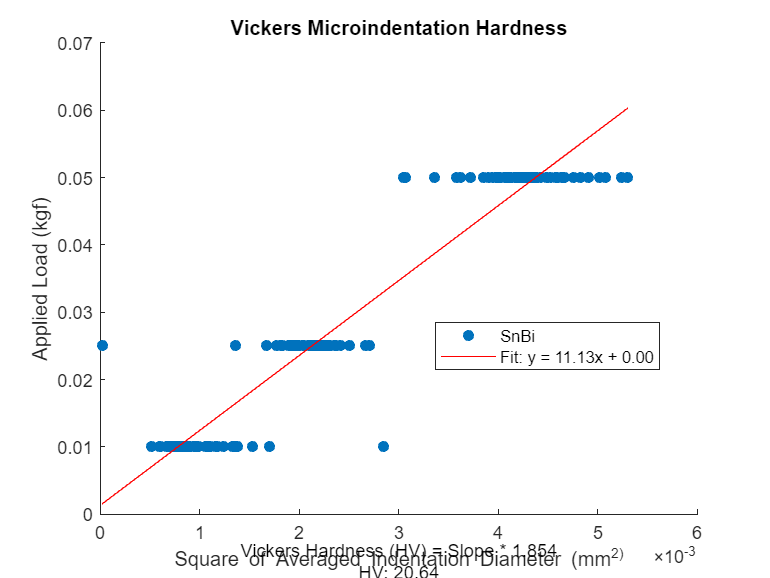


% Convert the average diameter from micrometers to millimeters
% Also exclude the first data point as it is more headers for the units in the .csv file
diameter_mm = data.averagediameter(2:end) / 1000; % Replace with column name from .csv file

% Calculate the square of the averaged indentation diameter
diameter_squared = diameter_mm.^2;

% Convert the applied load from gf to kgf
% Also exclude the first data point as it is more headers for the units in the .csv file
load_kgf = data.load(2:end) / 1000; % Replace with column name from .csv file

% Perform linear regression on the valid (non-NaN) data points
validIdx = ~isnan(diameter_squared) & ~isnan(load_kgf);
coeffs = polyfit(diameter_squared(validIdx), load_kgf(validIdx), 1);

% Calculate the HV value using the slope
HV = coeffs(1) * 1.854;

% Create the regression line equation
regression_line = coeffs(1) * diameter_squared(validIdx) + coeffs(2);

% Plot the data and regression line
figure;
scatter(diameter_squared(validIdx), load_kgf(validIdx), 'filled');
hold on;
plot(diameter_squared(validIdx), regression_line, 'r-');

% Add title and axis labels
xlabel('Square of Averaged Indentation Diameter (mm^2)');
ylabel('Applied Load (kgf)');
title('Vickers Microindentation Hardness');

% Add legend
legend('SnBi', sprintf('Fit: y = %.2fx + %.2f', coeffs(1), coeffs(2)), 'Location', 'best');

% Add HV value and the equation for determining Vickers hardness at the bottom of the graph
text(0.5, -0.1, sprintf('Vickers Hardness (HV) = Slope * 1.854\nHV: %.2f', HV), ...
     'HorizontalAlignment', 'center', 'Units', 'normalized', ...
     'FontSize', 10, 'FontWeight', 'normal');

hold off;